addpath('rawData\data_1\')

load('rawData\data_1\data_1.mat');

%暂时先只处理0.01s。别忘了最终是要处理整个文件的！
seq_sur1=seq_sur(1:(length(seq_sur)/50));
seq_ref1=seq_ref(1:(length(seq_sur)/50));
duration1=0.01;

plotSpectrum(seq_ref1,f_s)
drawDDCSpectrum(seq_ref1,f_s)
[f1,H1]=AfterLPFSpectrum(seq_ref1,f_s);

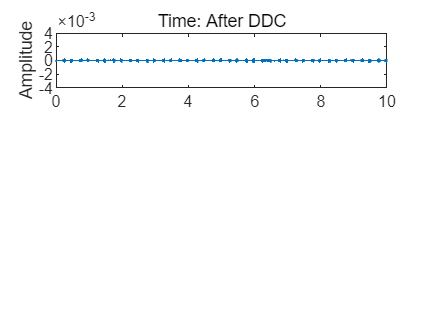

figure
y=sigAfterDDC(seq_ref1,f_s);
plotTimeSig(y,f_s,1,3,'Time: After DDC')

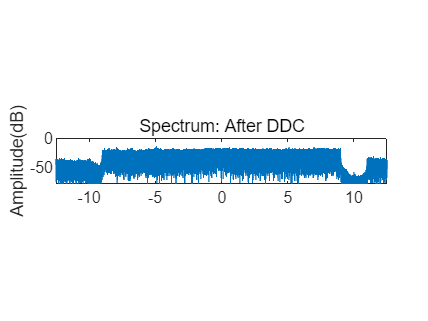

plotSpectrum(y,f_s,2,3,'Spectrum: After DDC')

function [f,H]=AfterLPFSpectrum(x,fs)
    N=length(x);
    f_ddc=-3e6;
    H=fftshift(fft(x));
    H=circshift(H,-f_ddc/fs*N);
    f=(-N/2:N/2-1)*fs/N;
    [b,a]=butter(4,9e6/(fs/2),'low');[Hf,~]=freqz(b,a,N/2);
    H_all=[flip(Hf);Hf];
    Norm=norm(H);
    H=H.*H_all';
    H=H./norm(H).*Norm;
    subplot(3,1,3),plot(f./10^6,20*log10(abs(H)))
    ylabel('Amplitude(dB)'),ylim([-80,0]),xlabel('Frequency(MHz)')
    title('Spectrum (after LPF)')
end



function drawDDCSpectrum(x,fs)
    N=length(x);
    f_ddc=-3e6;
    H=fftshift(fft(x));
    H=circshift(H,-f_ddc/fs*N);
    f=(-N/2:N/2-1)*fs/N;
    subplot(3,1,2),plot(f./10^6,20*log10(abs(H)))
    ylabel('Amplitude(dB)'),ylim([-80,0])
    title('Spectrum (after DDC)')
end

function t=xTime(x,fs)
    t=(0:length(x)-1)./fs;%将x轴用时间表示
end

function x_moved=sigAfterDDC(x,fs)
    f_ddc=-3e6;
    t=xTime(x,fs);
    x_moved=x.*exp(-1j*2*pi*f_ddc.*t);
end

function x_filtered=sigAfterLPF(x,fs)
    f_ddc=-3e6;
    bandwidth=9e6;
    t=xTime(x,fs);
    x=x.*exp(-1j*2*pi*f_ddc.*t);
    [b,a]=butter(20,bandwidth/(fs/2),'low');
    x_filtered=filter(b,a,x);
end

function plotTimeSig(x,fs,a,n,Title)
    if a==1
        figure
    end
    t=xTime(x,fs);
    subplot(n,1,a),plot(t.*1e3,x),title(Title)
    ylabel("Amplitude"),ylim([-4*1e-3,4*1e-3])
    if a==n
        xlabel("Time(ms)")
    end
end

function plotSpectrum(x,fs,a,n,Title)
    N=length(x);
    H=fftshift(fft(x));
    f=(-N/2:N/2-1)*fs/N;
    if a==1
        figure
    end
    figure,subplot(n,1,a),plot(f./10^6,20*log10(abs(H))),title(Title)
    ylabel('Amplitude(dB)'),ylim([-80,0])
    if a==n
        xlabel('Frequency(MHz)')
    end
end